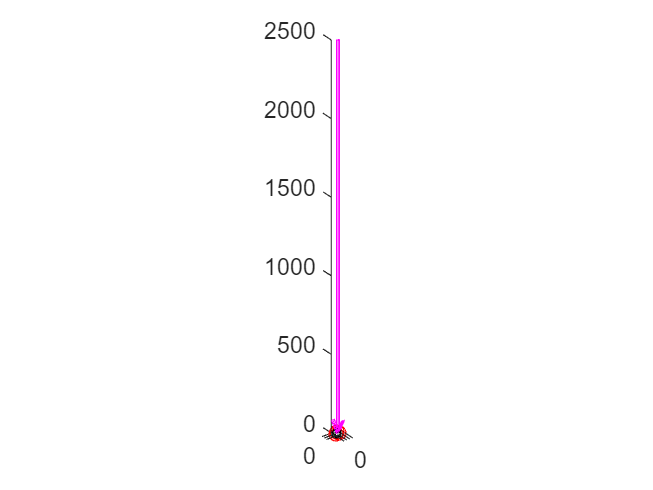

ans =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


clear all
clc
obj = CableStayedSuspension_Bridge;

% 1. 定义加劲梁：材料、截面、单元类型
girder_sectiondata = UserSection(6.3676,20,190.1827,193,36,8);
girder_materialdata = MaterialData_Q345;
Sec_girder = Section('主跨主梁Girder',girder_sectiondata);
Mat_girder = Material('主跨主梁Girder',girder_materialdata);
ET_girder = Beam188;

% 2. 定义加劲梁：几何
L = 10*ones(1,2);
CoordA_girder = [0,0,0];
CoordB_girder = [20,0,0];
girder = obj.buildGirder(CoordA_girder,CoordB_girder,L,Sec_girder,Mat_girder,ET_girder);

% 3. 提取点参数
PointA = girder.PointA;
PointM = girder.Point(2);
PointB = girder.PointB;

% 添加吊索
hanger_sectiondata = CircleSection(0.15/2);
hanger_materialdata = MaterialData_Q345;
Sec_hanger = Section('吊杆Hanger',hanger_sectiondata);
Mat_hanger = Material('吊杆Hanger',hanger_materialdata);
ET_hanger = Link10;

Point_HangerAnchor = Point(4,PointM.X,PointM.Y,PointM.Z+5);
hanger = obj.buildHanger(PointM,Point_HangerAnchor,girder,Structure.empty,Sec_hanger,Mat_hanger,ET_hanger);

% 4. 定义约束
support_DoF_1 = {'Ux','Uy','Uz','Rotx'};
support_DoF_2 = {'Uy','Uz','Rotx'};
constraint1 = obj.addConstraint(PointA,support_DoF_1,zeros(1,length(support_DoF_1)),'Name','梁端约束1');
constraint2 = obj.addConstraint(PointB,support_DoF_2,zeros(1,length(support_DoF_2)),'Name','梁端约束2');

support_DoF_3 = {'Ux','Uy','Uz'};
constraint3 = obj.addConstraint(Point_HangerAnchor,support_DoF_3,zeros(1,length(support_DoF_3)),'Name','吊索约束');
obj.setForceTo({hanger},2.05e9);% 通过调整这里的索力，进而调整实常数中的初应变。这里索力调整为2.05e9
% 5. 添加均布荷载
FullSpanLoad = UniformLoad(girder.Line,'Z',-250000000);
obj.addLoad(FullSpanLoad,'Name','二期恒载');

% 显示
obj.plot


% 5. 定义输出方式
obj.OutputMethod = OutputToAnsys(obj,"JobName",'SimplySupportedBridge',...
                                'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
                                'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test_StrainAndStress\SimplySupportedBridge',...
                                'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test_StrainAndStress\SimplySupportedBridge\main.mac',...
                                'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test_StrainAndStress\SimplySupportedBridge\result.out');

% 6. 输出
obj.output;
